## 定义网络架构

% Generator Network
numLatentInputs = 128;
embeddingDimension = 50;
numFilters = 64;
lgMultiple = 12;
filterSize = 5;
projectionSize = [5, 1, 1024];

layersGenerator = [
    imageInputLayer([1 1 numLatentInputs],'Normalization','none','Name','in')
    projectAndReshapeLayer(projectionSize,numLatentInputs,'proj');
    concatenationLayer(3,2,'Name','cat');

    transposedConv2dLayer([filterSize, 1],lgMultiple*numFilters,Stride=[3,1],Cropping="same")
    batchNormalizationLayer
    reluLayer
    transposedConv2dLayer([filterSize, 1],lgMultiple*numFilters,Stride=[3,1],Cropping="same")
    batchNormalizationLayer
    reluLayer
    transposedConv2dLayer([filterSize, 1],lgMultiple*numFilters,Stride=[3,1],Cropping="same")
    batchNormalizationLayer
    reluLayer
    transposedConv2dLayer([filterSize, 1],lgMultiple*numFilters,Stride=[3,1],Cropping="same")
    batchNormalizationLayer
    reluLayer
    transposedConv2dLayer([filterSize, 1],numInputChannels,Stride=[2,1],Cropping="same")];

lgraphGenerator = layerGraph(layersGenerator);

layers = [
    imageInputLayer([1 1],'Name','labels','Normalization','none')
    embedAndReshapeLayer(projectionSize(1:2),embeddingDimension,numClasses,'emb')];

lgraphGenerator = addLayers(lgraphGenerator,layers);
lgraphGenerator = connectLayers(lgraphGenerator,'emb','cat/in2');
dlnetGenerator = dlnetwork(lgraphGenerator);

% Discriminator Network

scale = 0.2;
dropoutProb = 0.5;
ldMultiple = 4;
inputSize = [lenaccelw lenaccelh numInputChannels];

layersDiscriminator = [
    imageInputLayer(inputSize,'Normalization','none','Name','in')
    dropoutLayer(dropoutProb)
    concatenationLayer(3,2,'Name','cat')

    convolution2dLayer([filterSize, 1],ldMultiple*numFilters,Stride=[3,1],Padding="same")
    leakyReluLayer(scale)
    dropoutLayer(dropoutProb)
    convolution2dLayer([filterSize, 1],ldMultiple*numFilters,Stride=[3,1],Padding="same")
    batchNormalizationLayer
    leakyReluLayer(scale)
    dropoutLayer(dropoutProb)
    convolution2dLayer([filterSize, 1],ldMultiple*numFilters,Stride=[3,1],Padding="same")
    batchNormalizationLayer
    leakyReluLayer(scale)
    dropoutLayer(dropoutProb)
    convolution2dLayer([filterSize, 1],ldMultiple*numFilters,Stride=[3,1],Padding="same")
    batchNormalizationLayer
    leakyReluLayer(scale)
    dropoutLayer(dropoutProb)
    convolution2dLayer([filterSize, 1],ldMultiple*numFilters,Stride=[4,1],Padding="same")
    batchNormalizationLayer
    leakyReluLayer(scale)
    dropoutLayer(dropoutProb)
    convolution2dLayer([filterSize, 1],numInputChannels,Stride=[3,1],Padding="same")];

lgraphDiscriminator = layerGraph(layersDiscriminator);

layers = [
    imageInputLayer([1 1],'Name','labels','Normalization','none')
    embedAndReshapeLayer(inputSize,embeddingDimension,numClasses,'emb')];

lgraphDiscriminator = addLayers(lgraphDiscriminator,layers);
lgraphDiscriminator = connectLayers(lgraphDiscriminator,'emb','cat/in2');
dlnetDiscriminator = dlnetwork(lgraphDiscriminator);

## Specify Training Options

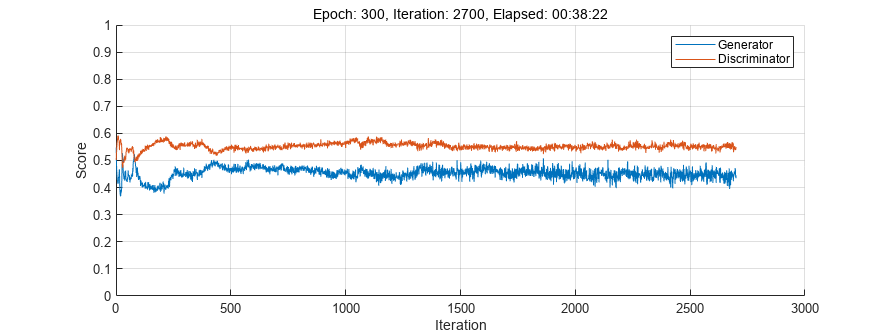

params.numLatentInputs = numLatentInputs;
params.numClasses = numClasses;
params.sizeData = [inputSize length(labeltra)];
params.numEpochs = 300;
params.miniBatchSize = 512;
params.executionEnvironment = "gpu";
% Specify the options for Adam optimizer
params.learnRate = 0.0002;
params.gradientDecayFactor = 0.5;
params.squaredGradientDecayFactor = 0.999;
% 开始训练
[dlnetGenerator,dlnetDiscriminator] = trainGAN(dlnetGenerator,dlnetDiscriminator,datastra,labeltra,params);

## 合成信号-1

rng default
dlXGeneratedNew = [];
dlYGeneratedNew = [];

for i = 1:4
    numTests = 1200;
    ZNew = randn(1,1,numLatentInputs,numTests,'single');
    dlZNew = gpuArray(dlarray(ZNew,'SSCB'));
    
    TNew = ones(1,1,1,numTests,'single');
    TNew(1,1,1,floor(numTests/3)+1:2*floor(numTests/3)) = single(2);
    TNew(1,1,1,2*floor(numTests/3+1):end) = single(3);
    dlTNew = gpuArray(dlarray(TNew,'SSCB'));
    dlXGNew = predict(dlnetGenerator,dlZNew,dlTNew)*stdtra+meantra;
    dlXGNew = squeeze(extractdata(gather(dlXGNew)));
    dlXGeneratedNew = cat(2,dlXGeneratedNew,dlXGNew);

    dlYGeneratedNew = cat(1,dlYGeneratedNew,squeeze(TNew));
end
clear i dlXGNew

datastra = datastra*stdtra+meantra;